# Lab 2 State Feedback and Observer

A system (input $u\left(t\right)$ and output $y\left(t\right)$)is given by a simple transfer function:


$$G\left(s\right)=\frac{0\ldotp 1}{\;\left(1+s\right)\left(0\ldotp 1+s\right)}$$


## Question 1: model

Give a state space model **sysol** of this system with states:


$${\left\lbrack x_{1\;} \;\;x_{2\;} \right\rbrack }^T ={\left\lbrack y\left(t\right)\;\;\frac{\textrm{dy}\left(t\right)}{\textrm{dt}}\right\rbrack }^T$$


and ouput ${\left\lbrack y\left(t\right)\;\;\frac{\textrm{dy}\left(t\right)}{\textrm{dt}}\right\rbrack }^T$ (assuming both states can be measured)

A = [0 1 ; -0.1 1.1];
B = [0 ; 0.1];
C = [1 0 ; 0 1];
D = 0;
sysol = ss(A,B,C,D)

sysol =
 
  A = 
         x1    x2
   x1     0     1
   x2  -0.1   1.1
 
  B = 
        u1
   x1    0
   x2  0.1
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



G = tf([0.1],[1 1.1 0.1])

G =
 
         0.1
  -----------------
  s^2 + 1.1 s + 0.1
 
Continuous-time transfer function.



## Question 2: state feedback

We first compute a state feedback assuming the two states are measurable

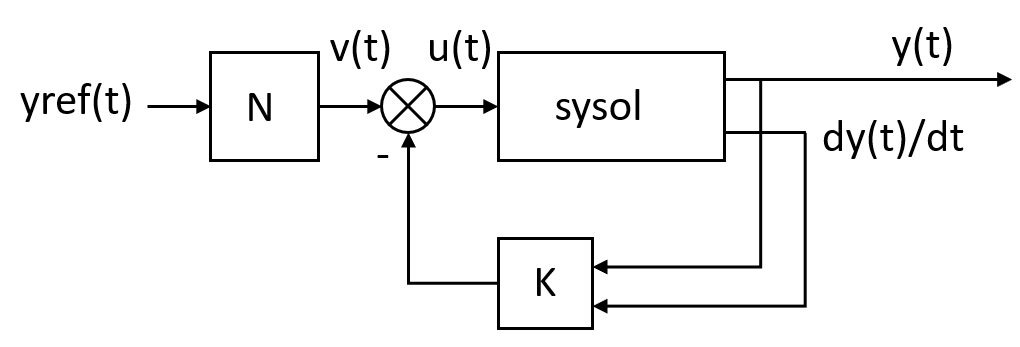

Using the matlab function **place**, compute the gain K of a state space feedback that guarantees a closed loop with damping $\sigma =0\ldotp 7$ and natural frequency $\omega {\;}_0 =1\;\textrm{rad}/s$

Give **syscl** the closed loop function between $v\left(t\right)$ and $y\left(t\right)$ 

Compute the value of the prefilter N for null steady state error with constant input. Method 1: compute the dcgain without prefilter N (matlab function dcgain) and compensate according to this result. Method 2: code the algorithm given page 71 of the slides;

p = roots([1 1.4 1]);
K = place(A,B,p)

K =      9    25


syscl = feedback(sysol,K);
dcg = dcgain(syscl)

dcg =     0.1000
         0



% the prefilter is used to correct the system for null steady state error.
% the dcgain is dependent on the feedback gain (the dynamics of the system)
% which is constrained because of the specific damping and cutoff frequency
% required. Hence, we need a prefilter gain to correct the dcgain. We
% cannot change the dcgain ourselves because it is constrained according to
% the feedback gain which in turn is constrained by the specific poles
% needed.
% syscl = 1/(Ks + K + (1/G))    K = 9

## Question 3: observer

We now assume that only $y\left(t\right)$ can be mesured. 

The dynamics of the observer is given by two poles: $\left\lbrack \begin{array}{cc}
-\textrm{po}-i\times \textrm{po} & -\textrm{po}+i\times \textrm{po}
\end{array}\right\rbrack$ with $\textrm{po}=10$

Compute the gain $L$ of the observer. 

Compute **sysobs** the state space model of the observer. The observer has input $\left\lbrack \begin{array}{c}
u\left(t\right)\\
y\left(t\right)
\end{array}\right\rbrack$and output $\left\lbrack \begin{array}{c}
\textrm{xest1}\left(t\right)\\
\textrm{xest2}\left(t\right)
\end{array}\right\rbrack$

## Question 4: simulation, combination of observer and state feedback

The Simulink file lab2.slx is provided for the simulation.

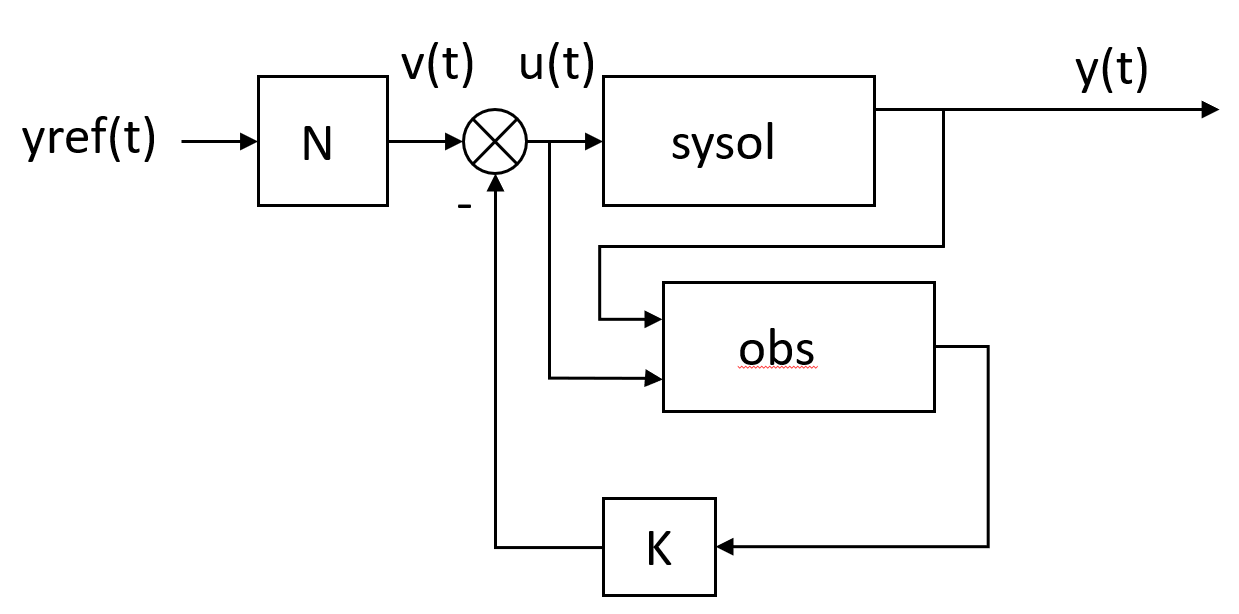

The following code allows to run the simulation from the command line, load and plot the interesting results.

simout=sim('lab2');

No system or file called 'lab2' found.

t = simout.logsout{1}.Values.Time;
yref = simout.logsout{1}.Values.Data;
u = simout.logsout{2}.Values.Data;
y = simout.logsout{3}.Values.Data;
plot(t,yref,t,y);legend('yref','y');
plot(t,u);legend('u');

Discuss the choice of:

- the closed loop natural frequency omega (try 10-100 times faster)

- the poles of the observer (try 10-100 times faster)